% A2.1

% System Parameters
m = 1;                
c = 2;                
k = 25;      

% Original Transfer Function without integrator
sys_original = tf(1, [m, c, k]);

% One Integrator
sys_with_one_integrator = tf(1, [1 0]) * sys_original

sys_with_one_integrator =
 
          1
  ------------------
  s^3 + 2 s^2 + 25 s
 
Continuous-time transfer function.
Model Properties



% Two Integrator
sys_with_two_integrators = tf([1 0], conv([1 0], [1 0])) * sys_original

sys_with_two_integrators =
 
           s
  --------------------
  s^4 + 2 s^3 + 25 s^2
 
Continuous-time transfer function.
Model Properties


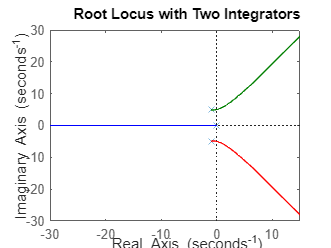


% Root Locus Analysis
figure;
rlocus(sys_with_two_integrators);
title('Root Locus with Two Integrators');


% Stability Analysis
poles = pole(sys_with_two_integrators);
if all(real(poles) < 0)
    fprintf('The system with two integrators can be stable.\n');
else
    fprintf('The system with two integrators may not be stable.\n');
end

The system with two integrators may not be stable.



% System Type Analysis
num_integrators = sum(ismember([1 0], sys_with_two_integrators.den{1}));
system_type = num_integrators;
fprintf('The system type number is %d.\n', system_type);

The system type number is 2.


% A3.2
% Define G2
G2 = zpk([], [0 -2 -5], 1)

G2 =
 
        1
  -------------
  s (s+2) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties



sisotool(G2);

% Adjust Gain for Fastest Settling Time
[~, y] = step(G2);
[~, idx] = min(abs(y - 1));
K = y(idx);
disp(['Gain for fastest settling time (step input): ', num2str(K)]);

Gain for fastest settling time (step input): 0.99472


% Steady State Error for Ramp Input
time = 0:0.01:10;  % Time vector

C =
 
  0.9947 s + 1.989
  ----------------
       s + 20
 
Continuous-time transfer function.
Model Properties


Gain for improved settling time (step input): 0.99472


alpha = 1;
ramp = t * alpha;  % Ramp input
H = lsim(G2, ramp, time);
disp(['Steady-state error for ramp input: ', num2str(H(end))]);

% Edit Compensator and Adjust Gain
C = K*(s + 2)/(s + 20);
G2_comp = G2 * C;
[~, y] = step(G2_comp);
[~, idx] = min(abs(y - 1));
K = y(idx);
disp(['Gain for improved settling time (step input): ', num2str(K)]);

Gain for improved settling time (step input): 0.99472


% Ess for Ramp Input with Compensator
H = lsim(G2_comp, ramp, time);
disp(['Steady-state error for ramp input with compensator: ', num2str(H(end))]);

Steady-state error for ramp input with compensator: 12.3101


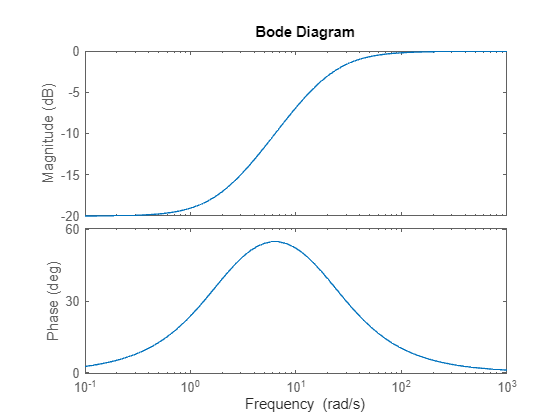


% Bode Plot of Compensator
bode(C);


% Check if Compensator is "Implementable"
[Gm, Pm] = bode(C, 1e6);
disp(['Gain margin (dB): ', num2str(20*log10(Gm(end)))]);

Gain margin (dB): -0.046011


disp(['Phase margin (deg): ', num2str(Pm(end))]);

Phase margin (deg): 0.0010313
